Здесь место для рефлексии.

Если малый дрейф, то малая жёсткость

Дрейф зависит от угла поворота шарнира, который в свою очередь зависиит от усилия на шарнир.

У шарнира есть левая и правая часть. Условно фиксируем левую часть, допуская, что у неё нулеой дрейф. У правой часть весь дрейф.

addpath("C:\dvogureckiy99\2_Education\ITMO\DMS\SPACAR")
clear; clc;
%addpath('spacar')
E      = 2.95*1e9;    %Young's modulus 2.95*1у9
nu = 0.39; % Puasson coefficient
G = 0.5*E/(1+nu); %shear modulus  
rho    = 1270;        %density
yield_stress = 76.6; 

L      = 20e-3;       %length [20 60]1e3 with step 1e-4                 all 400    
H      = 10e-3;       %width  [10 50]1e3 with step 1e-4                 all 400
W      = 0.0005;      %thickness from 5*4e-4 with step [5 25]4e-4    all 20
Stroke = deg2rad(70); %full stroke                                          70 always
steps = 3;           %loadsteps 

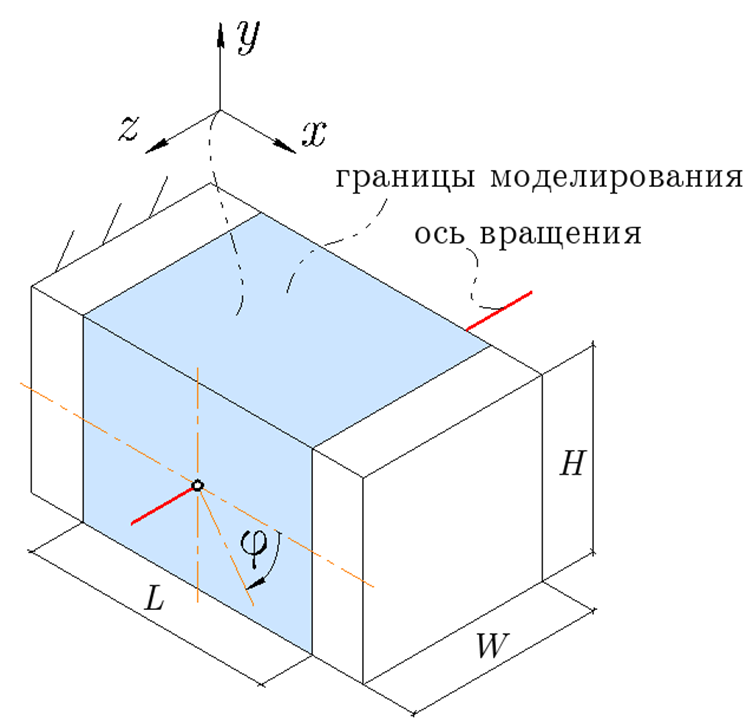

# **1. Blade Flexure**

% linspace(1,9,9)
N = 11;
nodes = [linspace(0,L,N)',zeros(N,1),zeros(N,1)];
n = size(nodes,1);
elements = [];
for i=1:n-1
    elements = [elements;i,i+1];
end
nprops(1).fix   = true; 
M = 1.1280328000000182; % 65.767 grad
% M = 3.0892327760299634; % pi
% M = 6.178465552059927; % 2pi
% M = 12.356931104119854; %4pi
F=30;
l_Fext = 0.01;
if exist('F','var')
nprops(int32((l_Fext/L)*N)).force = [0,F,0];
end
% nprops(n).rot_z = Stroke;

%flexures
eprops(1).elems = linspace(1,n-1,n-1);
eprops(1).flex = [3 4];
% eprops(1).nbeams = 1;
eprops(1).emod = E;
eprops(1).smod = G;
eprops(1).dens = rho;
eprops(1).cshape ='rect';
eprops(1).dim = [H W];
eprops(1).orien = [0 0 1];
eprops(1).color = 'blue';
eprops(1).cw = true;

opt.filename = 'simple_beam';
opt.loadsteps = steps;
opt.silent = true;

out = spacarlight(nodes,elements,nprops,eprops,opt);

P1x = 1e3*out.node(n).p(1,:);
P1y = 1e3*out.node(n).p(2,:);
q1 = rad2deg(out.node(n).r_eulzyx(1,:));
q11 = 2*rad2deg(atan2(P1y, P1x));
%ICR
k = tan(deg2rad(q1));
b = P1y - P1x.*k;
for i = 1:(steps-1)
    x_ICR1(i) = (b(i+1) - b(i))/(k(i) - k(i+1));
    y_ICR1(i) = k(i)*x_ICR1(i) + b(i);
end
L_P1 = sqrt(P1x.^2 + P1y.^2);
L_P1e = 100*(1e3*L - L_P1(end))/(1e3*L)

L_P1e = 5.0618

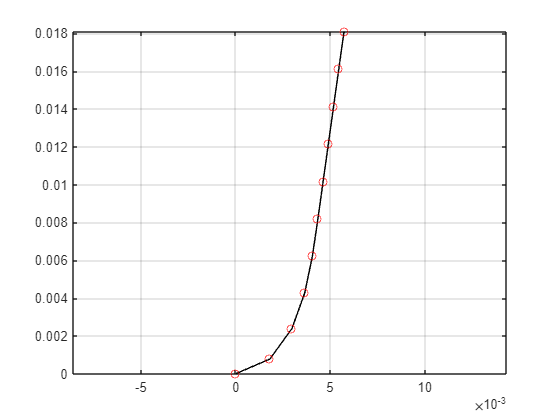

x_all_nodes = [];
y_all_nodes = [];
for i=1:n
    x_all_nodes = [x_all_nodes;out.node(i).p(1,steps)];
    y_all_nodes = [y_all_nodes;out.node(i).p(2,steps)];
end
figure;
plot(x_all_nodes,y_all_nodes,"-k");grid on;hold on;%axis equal;
plot(x_all_nodes,y_all_nodes,"or");
axis("equal")

phi_end = q1(end)

phi_end = 82.0664

rad2deg(out.node(n).r_eulzyx(1,end))

ans = 82.0664

out.node(n).p(1,steps)

ans = 3.7560e-04

out.node(n).p(2,steps)

ans = 2.2668e-05

q11

q11 =          0    7.3470   14.6943   22.0423   29.3913   36.7417   44.0937   51.4477   58.8041   66.1632   73.5253   80.8907   88.2599   95.6332  103.0108  110.3932  117.7807  125.1736  132.5723  139.9772  147.3887  154.8070  162.2325  169.6656  177.1068  184.5563  192.0145  199.4819  206.9587  214.4455  221.9425  229.4502  236.9690  244.4994  252.0416  259.5962  267.1636  274.7441  282.3383  289.9466  297.5694  305.2072  312.8604  320.5296  328.2153  335.9178  343.6377  351.3756  359.1319    6.9072


ans = -0.0031

R = 0.0032

L_all = 0;
for i=2:n
    L_all = L_all + sqrt( (out.node(i).p(1,steps)-out.node(i-1).p(1,steps))^2 + (out.node(i).p(2,steps)-out.node(i-1).p(2,steps))^2);
    
end
L_all

L_all = 0.0189

x_all_nodes = [];
y_all_nodes = [];
for i=1:n
    x_all_nodes = [x_all_nodes;out.node(i).p(1,steps)];
    y_all_nodes = [y_all_nodes;out.node(i).p(2,steps)];
end
R = E*W^3*H/12/M

R = 0.0174

x_c1 = linspace(min(x_all_nodes)-(R+min(x_all_nodes)),max(x_all_nodes)+(R-max(x_all_nodes)),100);
y_c1 = -sqrt(R.^2-x_c1.^2)+R;
q_n = 2*atan(y_all_nodes(end)/x_all_nodes(end))*180/pi 

q_n = 65.8720

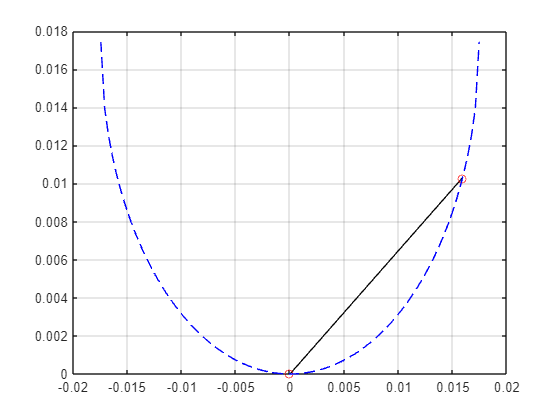

if x_all_nodes(end)<max(x_all_nodes)
    x_c2 = linspace(min(x_all_nodes)-(R+min(x_all_nodes)),max(x_all_nodes)+(R-max(x_all_nodes)),100);
    y_c2 = sqrt(R.^2-x_c2.^2)+R;
end
figure;
plot(x_all_nodes,y_all_nodes,"-k");grid on;hold on;%axis equal;
plot(x_all_nodes,y_all_nodes,"or");
plot(x_c1,y_c1,"--b");

if x_all_nodes(end)<max(x_all_nodes)
    plot(x_c2,y_c2,"--b");
end


nodes = [0  0  0;  %node 1   
         L  0  0]; %node 2
n = 2; %output node
elements = [1 2]; %blade
nprops(1).fix   = true;
nprops(n).rot_z = Stroke;

%flexures
eprops(1).elems = [1];
eprops(1).emod = E;
eprops(1).smod = G;
eprops(1).dens = rho;
eprops(1).cshape ='rect';
eprops(1).dim = [W H];
eprops(1).orien = [0 0 1];
%eprops(1).nbeams = 2;
eprops(1).flex = 1:6;
eprops(1).color = 'blue';
eprops(1).cw = true;

opt.filename = '1_Blade_Flexure';
opt.loadsteps = steps;
opt.silent = true;

opt = struct with fields:
     filename: '1_Blade_Flexure'
    loadsteps: 10
       silent: 1



out = spacarlight(nodes,elements,nprops,eprops,opt);

P1x = 1e3*out.node(n).p(1,:);
P1y = 1e3*out.node(n).p(2,:);
q1 = rad2deg(out.node(n).r_eulzyx(1,:));
q11 = 2*rad2deg(atan2(P1y, P1x));
%ICR
k = tan(deg2rad(q1));
b = P1y - P1x.*k;
for i = 1:(steps-1)
    x_ICR1(i) = (b(i+1) - b(i))/(k(i) - k(i+1));
    y_ICR1(i) = k(i)*x_ICR1(i) + b(i);
end
L_P1 = sqrt(P1x.^2 + P1y.^2);
L_P1e = 100*(1e3*L - L_P1(end))/(1e3*L)

L_P1e = 5.4832

q11 - q1

ans = 1.0e-14 *

         0   -0.1776    0.3553         0         0    0.7105   -0.7105    0.7105         0         0


save('data_q.mat',"q1","-nocompression")

out.node(n).p

ans =     0.0200    0.0199    0.0198    0.0195    0.0191    0.0186    0.0180    0.0173    0.0165    0.0155
         0    0.0013    0.0025    0.0038    0.0050    0.0063    0.0075    0.0086    0.0098    0.0108
         0         0         0         0         0         0         0         0         0         0


out.ndof

ans = 6

M1 = out.node(n).Mreac(3,:);
Kx1(:) = 1./out.node(n).CMglob(1,1,:);
Ky1(:) = 1./out.node(n).CMglob(2,2,:);
Kz1(:) = 1./out.node(n).CMglob(3,3,:);
Krotx1(:) = 1./out.node(n).CMglob(4,4,:);
Kroty1(:) = 1./out.node(n).CMglob(5,5,:);
% Krotz1(:) = 1./out.node(n).CMglob(6,6,:);
Krotz1 = diff(M1)./diff(q1);
% clearvars nodes elements nprops eprops opt; %clear structs before analyzing new hinge

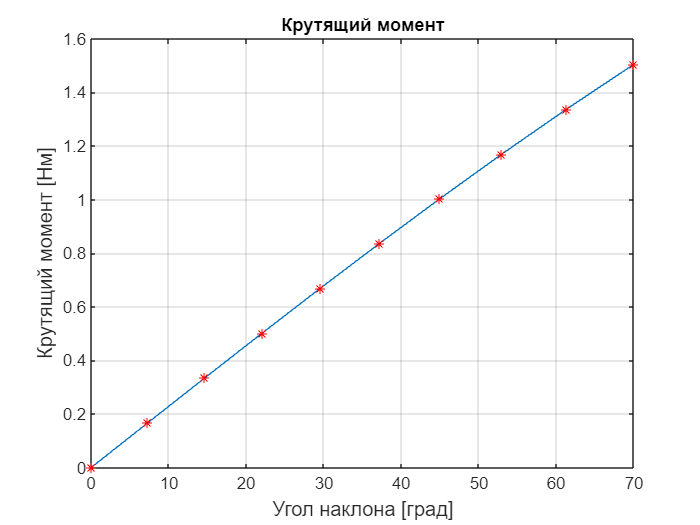

figure;plot(q1,M1);hold on;plot(q1,M1,'*r');title('Крутящий момент');grid on;xlabel('Угол наклона [град]', 'fontsize', 12);ylabel('Крутящий момент [Нм]', 'fontsize', 12);

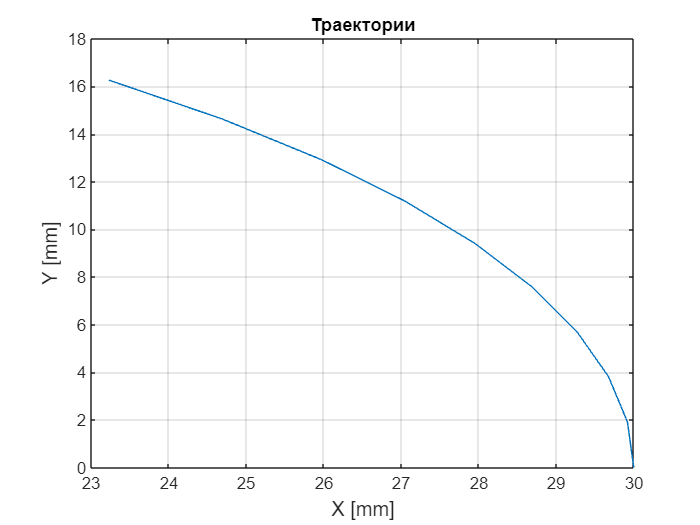

figure;plot(P1x,P1y);title('Траектории');grid on;xlabel('X [mm]', 'fontsize', 12);ylabel('Y [mm]', 'fontsize', 12);

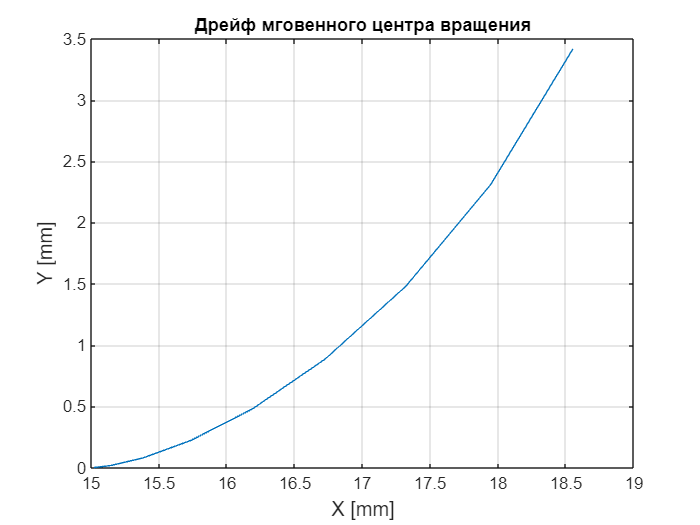

figure; plot(x_ICR1,y_ICR1); title('Дрейф мговенного центра вращения'); grid on; xlabel('X [mm]', 'fontsize', 12); ylabel('Y [mm]', 'fontsize', 12);

Kx_rate1 = 100*(Kx1(1)-Kx1(end))/Kx1(1) %потеря жёсткости 1 шарнира в %

Kx_rate1 = 99.1702

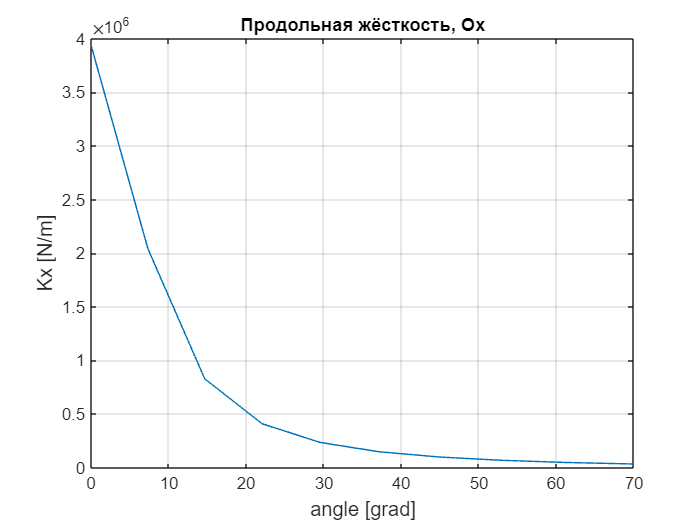

figure; plot(q1,Kx1); title('Продольная жёсткость, Ox'); grid on; xlabel('angle [grad]', 'fontsize', 12); ylabel('Kx [N/m]', 'fontsize', 12);

Ky_rate1 = 100*(Ky1(1)-Ky1(end))/Ky1(1) %потеря жёсткости 1 шарнира в %

Ky_rate1 = 6.7455

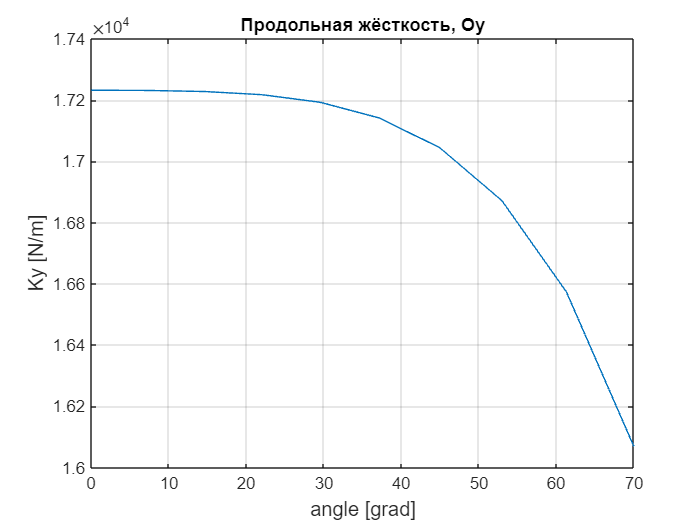

figure; plot(q1,Ky1); title('Продольная жёсткость, Oy'); grid on; xlabel('angle [grad]', 'fontsize', 12); ylabel('Ky [N/m]', 'fontsize', 12);

Kz_rate1 = 100*(Kz1(1)-Kz1(end))/Kz1(1) %потеря жёсткости 1 шарнира в %

Kz_rate1 = 69.3560

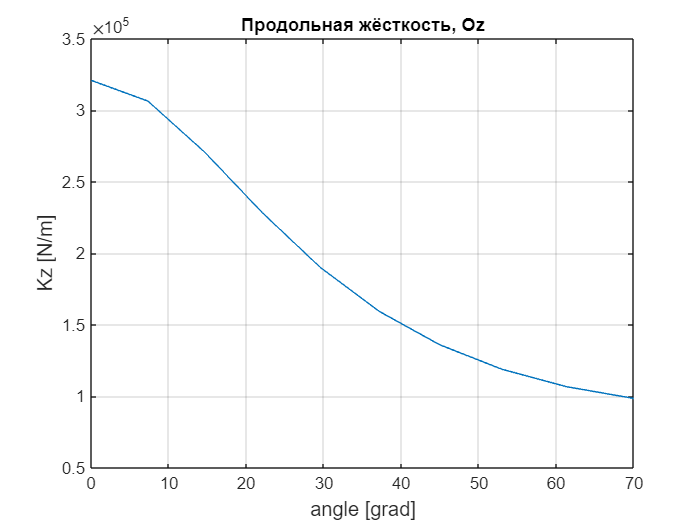

figure; plot(q1,Kz1); title('Продольная жёсткость, Oz'); grid on; xlabel('angle [grad]', 'fontsize', 12); ylabel('Kz [N/m]', 'fontsize', 12);

Krotx_rate1 = 100*(Krotx1(1)-Krotx1(end))/Krotx1(1) %потеря жёсткости 1 шарнира в %

Krotx_rate1 = -47.2336

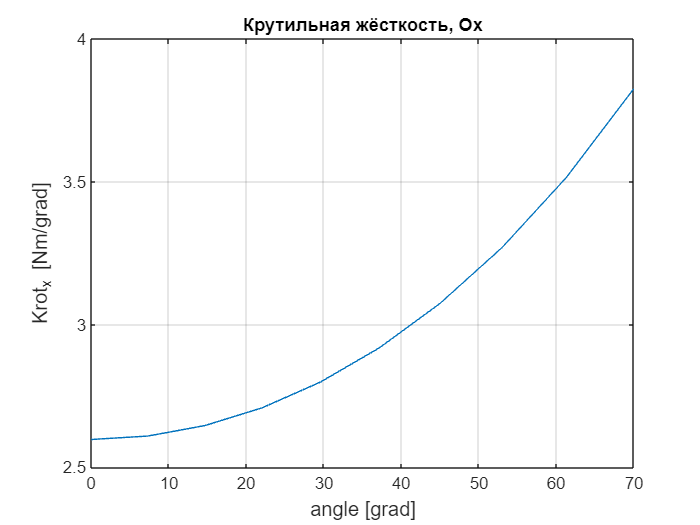

figure; plot(q1,Krotx1);title('Крутильная жёсткость, Ox');grid on;xlabel('angle [grad]', 'fontsize', 12);ylabel('Krot_x [Nm/grad]', 'fontsize', 12);

Kroty_rate1 = 100*(Kroty1(1)-Kroty1(end))/Kroty1(1) %потеря жёсткости 1 шарнира в %

Kroty_rate1 = 94.2247

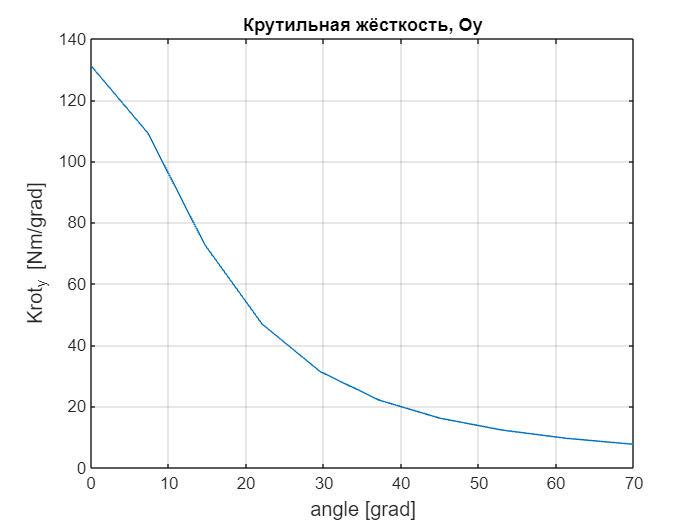

figure;plot(q1,Kroty1);title('Крутильная жёсткость, Oy');grid on;xlabel('angle [grad]', 'fontsize', 12);ylabel('Krot_y [Nm/grad]', 'fontsize', 12);

Krotz_rate1 = 100*(Krotz1(1)-Krotz1(end))/Krotz1(1) %потеря жёсткости 1 шарнира в %

Krotz_rate1 = 15.9318

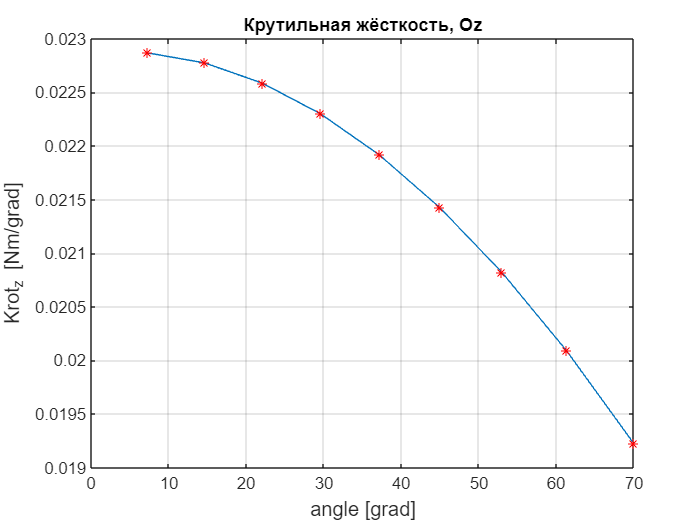

figure;plot(q1(2:end)-q1(1),Krotz1);hold on;plot(q1(2:end)-q1(1),Krotz1,'*r');title('Крутильная жёсткость, Oz');grid on;xlabel('angle [grad]', 'fontsize', 12);ylabel('Krot_z [Nm/grad]', 'fontsize', 12);

Krotz1

Krotz1 =     0.1368    0.1339    0.1280    0.1185
